# Chapter 8:  Tree-Based Methods

## 8.3 Lab: Decision Trees

### 8.3.1 Fitting Classification Trees

[Fit binary decision tree for multiclass classification](https://www.mathworks.com/help/stats/fitctree.html#bt6cr7t_sep_shared-Tbl) 

[ClassificationTree class](https://www.mathworks.com/help/stats/classificationtree-class.html)

clear all; clc; close all;
Carseats = readtable("Data\Carseats.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Carseats.ShelveLoc = categorical(Carseats.ShelveLoc);
Carseats.Urban = categorical(Carseats.Urban);
Carseats.US = categorical(Carseats.US);
High(Carseats.Sales <= 8,1) = {'No'};
High(Carseats.Sales > 8,1) = {'Yes'};
High = categorical(High);
Carseats = addvars(Carseats,High);

treeCarseats = fitctree(Carseats,'High ~ CompPrice + Income + Advertising + Population + Price + ShelveLoc + Age + Education + Urban + US')

treeCarseats =   ClassificationTree
           PredictorNames: {'CompPrice'  'Income'  'Advertising'  'Population'  'Price'  'ShelveLoc'  'Age'  'Education'  'Urban'  'US'}
             ResponseName: 'High'
    CategoricalPredictors: [6 9 10]
               ClassNames: [No    Yes]
           ScoreTransform: 'none'
          NumObservations: 400


  Properties, Methods


Display the tree structure

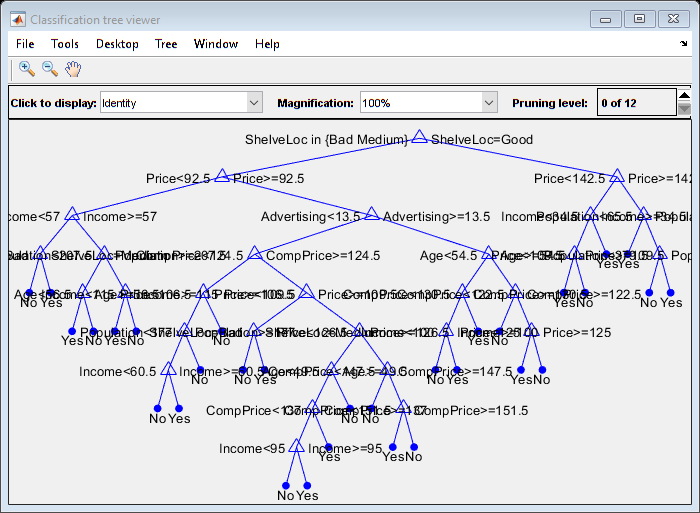

view(treeCarseats,'Mode','graph')

Display the split criterion 

view(treeCarseats)


Decision tree for classification
 1  if ShelveLoc in {Bad Medium} then node 2 elseif ShelveLoc=Good then node 3 else No
 2  if Price<92.5 then node 4 elseif Price>=92.5 then node 5 else No
 3  if Price<142.5 then node 6 elseif Price>=142.5 then node 7 else Yes
 4  if Income<57 then node 8 elseif Income>=57 then node 9 else Yes
 5  if Advertising<13.5 then node 10 elseif Advertising>=13.5 then node 11 else No
 6  if Income<34.5 then node 12 elseif Income>=34.5 then node 13 else Yes
 7  if Population<65.5 then node 14 elseif Population>=65.5 then node 15 else No
 8  if ShelveLoc=Bad then node 16 elseif ShelveLoc=Medium then node 17 else No
 9  if Population<207.5 then node 18 elseif Population>=207.5 then node 19 else Yes
10  if CompPrice<124.5 then node 20 elseif CompPrice>=124.5 then node 21 else No
11  if Age<54.5 then node 22 elseif Age>=54.5 then node 23 else Yes
12  if Price<109.5 then node 24 elseif Price>=109.5 then node 25 else Yes
13  class = Yes
14  class = Yes
15  if Populat

rng default; % For reproducibility
cv = cvpartition(height(Carseats),'holdout',0.5);
train = cv.training;
test = cv.test;
treeCarseats = fitctree(Carseats(train,:),'High ~ CompPrice + Income + Advertising + Population + Price + ShelveLoc + Age + Education + Urban + US');
treePred = predict(treeCarseats,Carseats(test,:));
confusiontable(treePred, Carseats.High(test))

ans = 2×2 table
                     . No    . Yes
                     ____    _____

    treePred. No      96      30  
    treePred. Yes     22      52  


(96 + 52)/200

ans = 0.7400

% or 
% confusionchart(treePred,Carseats.High(test));

**Find the Best Pruning Level Using Cross Validation**

Compute the 10-fold cross-validation error for each subtree except for the highest pruning level. Specify to return the best pruning level over all subtrees.

rng default; % For reproducibility
m = max(treeCarseats.PruneList) - 1;
[E,~,Nleaf,BestLevel] = cvloss(treeCarseats,'SubTrees',0:m,'KFold',10);

Plot the Error (loss) for tree as a function of Number of leaves of tree

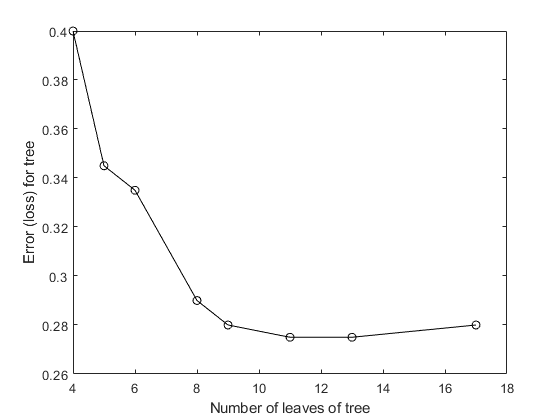

plot(Nleaf,E,'Marker','o','Color','k');
xlabel('Number of leaves of tree'); ylabel('Error (loss) for tree');

% Nleaf(E == min(E))

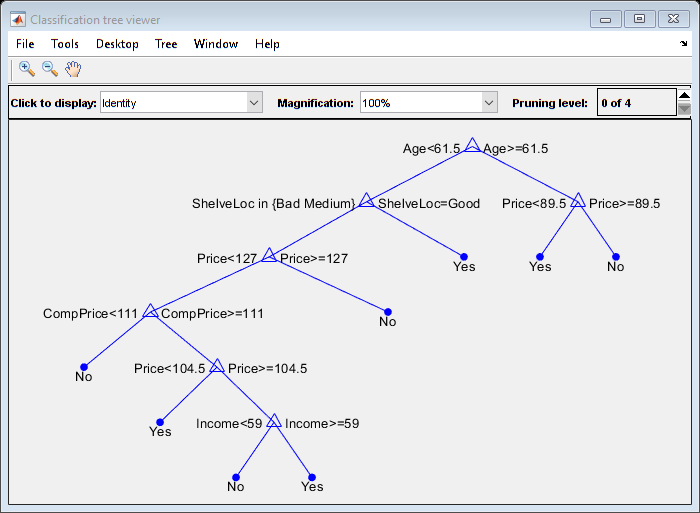

pruneCarseats = prune(treeCarseats,'Level',BestLevel);
view(pruneCarseats,'Mode','graph')

treePred = predict(pruneCarseats,Carseats(test,:));
confusiontable(treePred, Carseats.High(test))

ans = 2×2 table
                     . No    . Yes
                     ____    _____

    treePred. No      94      31  
    treePred. Yes     24      51  


If we increase the value of nodes, we obtain a larger pruned tree with lower classification accuracy

pruneCarseats = prune(treeCarseats,'Nodes',15);
treePred = predict(pruneCarseats,Carseats(test,:));
confusiontable(treePred, Carseats.High(test))

ans = 2×2 table
                     . No    . Yes
                     ____    _____

    treePred. No      98      32  
    treePred. Yes     20      50  


### 8.3.2 Fitting Regression Trees

clear all; clc; close all;
Boston = readtable("Data\Boston.csv", 'TreatAsEmpty',{'?','NA','N/A'} );
rng default
cv = cvpartition(height(Boston),'holdout',0.5); % cv.training and cv.test
treeBoston = fitrtree(Boston(cv.training,1:end-1),Boston(cv.training,end))

treeBoston =   RegressionTree
           PredictorNames: {'crim'  'zn'  'indus'  'chas'  'nox'  'rm'  'age'  'dis'  'rad'  'tax'  'ptratio'  'black'  'lstat'}
             ResponseName: 'medv'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 253


  Properties, Methods


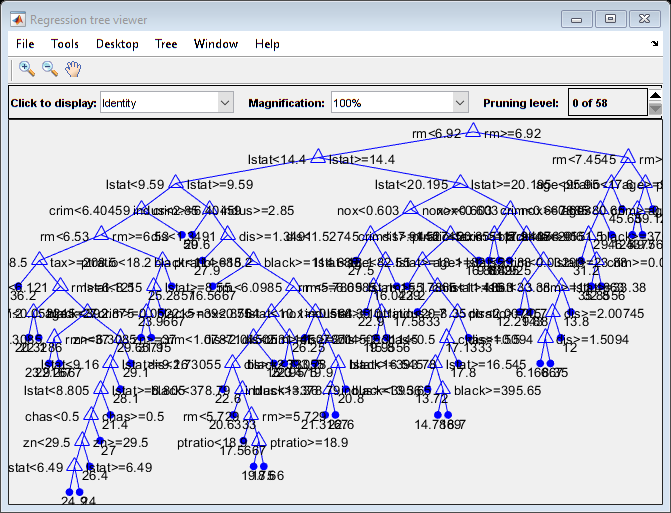

view(treeBoston,'Mode','graph');

rng default; % For reproducibility
m = max(treeBoston.PruneList) - 1;
[E,SE,Nleaf,BestLevel] = cvloss(treeBoston,'SubTrees',0:m,'KFold',10);

Plot the Error (loss) for tree as a function of Number of leaves of tree

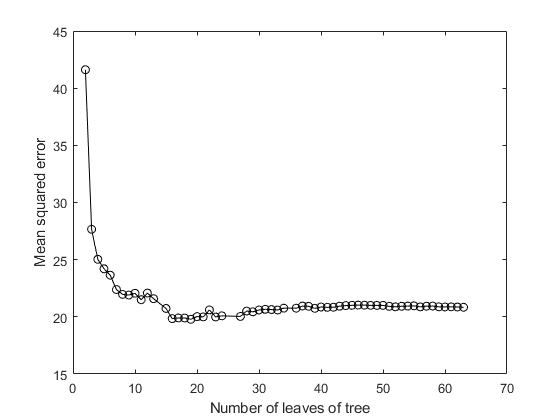

plot(Nleaf,E,'Marker','o','Color','k');
xlabel('Number of leaves of tree'); ylabel('Mean squared error');

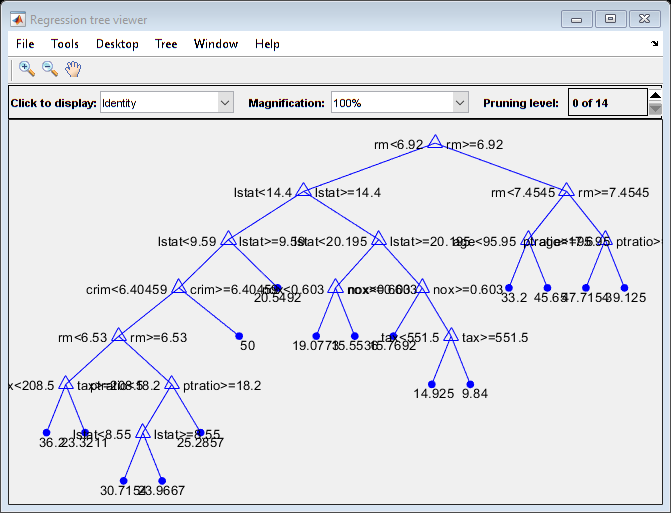

pruneBoston = prune(treeBoston,'Level',BestLevel);
view(pruneBoston,'Mode','graph')

In keeping with the cross-validation results, we use the unpruned tree to make predictions on the test set. 

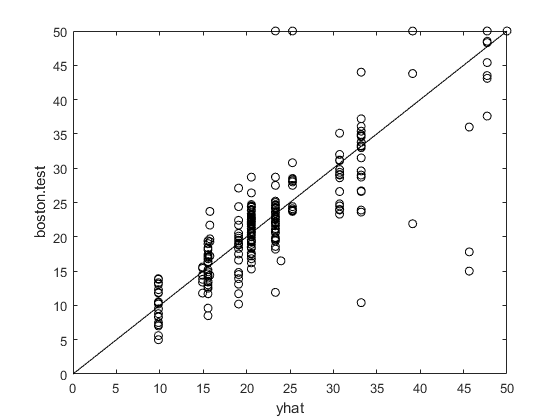

yhat = predict(pruneBoston,Boston(cv.test,1:end-1));
plot(yhat,Boston{cv.test,end},'Marker','o','Color','k','LineStyle','none'); hold on;
line([0,50],[0,50],'Color','k');
xlabel('yhat'); ylabel('boston.test');
hold off;

Mean-square testing error:

mean((yhat - Boston{cv.test,end}).^2)

ans = 26.7108

% or
loss(pruneBoston,Boston(cv.test,1:end-1),Boston(cv.test,end))

ans = 26.7108

### 8.3.3 Bagging and Random Forests

**a) Bagging**

[TreeBagger](https://www.mathworks.com/help/stats/treebagger-class.html), [TreeBagger class](https://www.mathworks.com/help/stats/treebagger-class.html)

[bagging](https://www.mathworks.com/help/stats/treebagger.html) is a special case of [Random Forests](https://www.mathworks.com/help/stats/select-predictors-for-random-forests.html) , when $m=p$, which means that it needs to be set: 'NumPredictorsToSample', 'all'

bagBoston = TreeBagger(500,Boston(cv.training,1:end-1),Boston(cv.training,end),'Method','regression',...
    'NumPredictorsToSample','all','OOBPredictorImportance','on')

bagBoston =   TreeBagger
Ensemble with 500 bagged decision trees:
                    Training X:             [253x13]
                    Training Y:              [253x1]
                        Method:           regression
                 NumPredictors:                   13
         NumPredictorsToSample:                  all
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []

  Properties, Methods


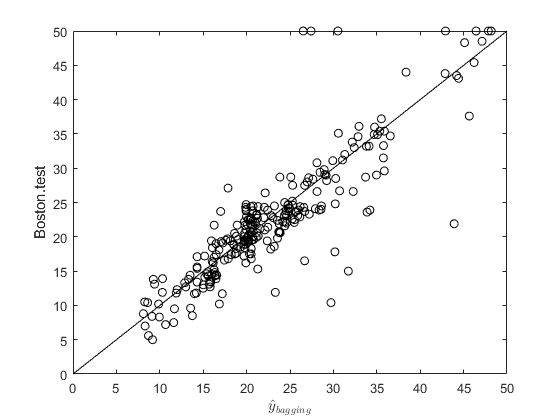

yhatBag = predict(bagBoston,Boston(cv.test,:));
plot(yhatBag,Boston{cv.test,"medv"},'o','Color','k');
hold on;
line([0 50], [0 50],'Color','k');
xlabel('$$\hat{y}_{bagging}$$','Interpreter','Latex');
ylabel('Boston.test');
hold off;

Compute the test set MSE

mean((yhatBag - Boston{cv.test,"medv"}).^2)

ans = 19.1956

% or
error(bagBoston,Boston(cv.test,1:end-1),Boston(cv.test,end),'Mode','ensemble')

ans = 19.1956

Change the number of trees grown NumTrees = 25

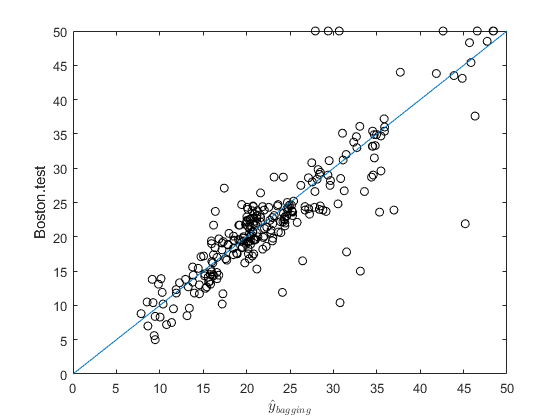

bagBoston = TreeBagger(25,Boston(cv.training,1:end-1),Boston(cv.training,end),'Method','regression',...
    'NumPredictorsToSample','all','OOBPredictorImportance','on');
yhatBag = predict(bagBoston,Boston(cv.test,:));
plot(yhatBag,table2array(Boston(cv.test,"medv")),'o','Color','k');
hold on;
line([0 50], [0 50]); 
xlabel('$$\hat{y}_{bagging}$$','Interpreter','Latex');
ylabel('Boston.test');

mean((yhatBag - Boston{cv.test,"medv"}).^2)

ans = 19.9887

**b) Random Forests**

rfBoston = TreeBagger(500,Boston(cv.training,1:end-1),Boston(cv.training,end),'Method','regression',...
    'OOBPredictorImportance','on')

rfBoston =   TreeBagger
Ensemble with 500 bagged decision trees:
                    Training X:             [253x13]
                    Training Y:              [253x1]
                        Method:           regression
                 NumPredictors:                   13
         NumPredictorsToSample:                    5
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []

  Properties, Methods


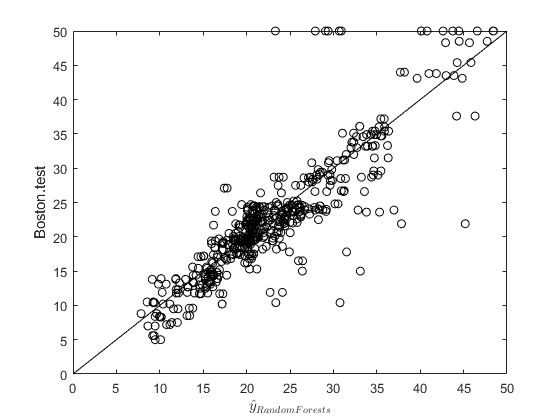

yhatRf = predict(rfBoston,Boston(cv.test,:));
plot(yhatRf,table2array(Boston(cv.test,"medv")),'o','Color','k');
hold on;
line([0 50], [0 50],'Color','k'); 
xlabel('$$\hat{y}_{Random Forests}$$','Interpreter','Latex');
ylabel('Boston.test');
hold off

mean((yhatRf - Boston{cv.test,"medv"}).^2)

ans = 17.1313

Plot the predictors sorted on importance

array2table(rfBoston.OOBPermutedPredictorDeltaError.','RowNames',rfBoston.PredictorNames,'VariableNames',{'OOBPermutedPredictorDeltaError'})

ans = 13×1 table
               OOBPermutedPredictorDeltaError
               ______________________________

    crim                   0.46431           
    zn                    0.066799           
    indus                  0.45435           
    chas                   0.19008           
    nox                    0.52956           
    rm                       1.418           
    age                    0.46208           
    dis                    0.50718           
    rad                    0.15093           
    tax                    0.32327           
    ptratio                0.44168           
    black                  0.23596           
    lstat                   1.2787           


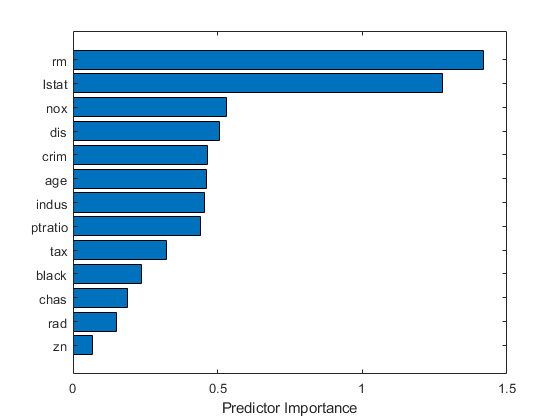

[predImportance,sortedIndex] = sort(rfBoston.OOBPermutedPredictorDeltaError);
figure;
barh(predImportance)
set(gca,'ytickLabel',rfBoston.PredictorNames(sortedIndex))
xlabel('Predictor Importance')

### 8.3.4 Boosting

[fitrensemble](https://www.mathworks.com/help/stats/fitrensemble.html), [Regression Tree Ensembles](https://www.mathworks.com/help/stats/regression-tree-ensembles.html), [Regression with Boosted Decision Trees](https://uk.mathworks.com/products/demos/machine-learning/boosted-regression.html)

Train a Regression Tree Using the Housing Data

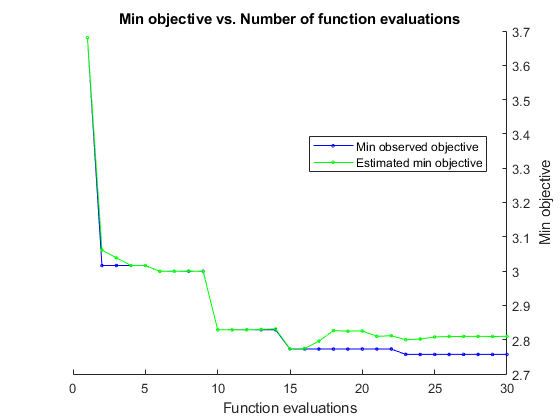

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      3.6804 |      1.5298 |      3.6804 |      3.6804 |          Bag |           22 |            - |           18 |
|    2 | Best   |      3.0163 |     0.94432 |      3.0163 |      3.0613 |      LSBoost |           12 |      0.72575 |           23 |
|    3 | Accept |      3.9302 |      17.227 |      3.0163 |      3.0387 |          Bag |          451 |            - |           43 |
|    4 | Accept |       3.127 |      7.9692 |      3.0163 |   

boostBoston =   classreg.learning.regr.RegressionEnsemble
                       PredictorNames: {'crim'  'zn'  'indus'  'chas'  'nox'  'rm'  'age'  'dis'  'rad'  'tax'  'ptratio'  'black'  'lstat'}
                         ResponseName: 'medv'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 253
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 10
                               Method: 'LSBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [10×1 double]
                   FitInfoDescription: {2×1 cell}
                       Regularization: []


  Pro

tic
boostBoston = fitrensemble(Boston(cv.training,:),'medv','OptimizeHyperparameters','auto')

toc

Elapsed time is 200.912166 seconds.


Estimates of predictor importance for regression  ensemble

array2table(predictorImportance(boostBoston)','RowNames',boostBoston.PredictorNames,'VariableNames',{'Predictor importance'})

ans = 13×1 table
               Predictor importance
               ____________________

    crim             0.015954      
    zn                      0      
    indus            0.011397      
    chas              0.01313      
    nox              0.029191      
    rm                0.78029      
    age             0.0090381      
    dis              0.035214      
    rad              0.001657      
    tax             0.0046769      
    ptratio          0.014258      
    black           0.0099462      
    lstat             0.37319      


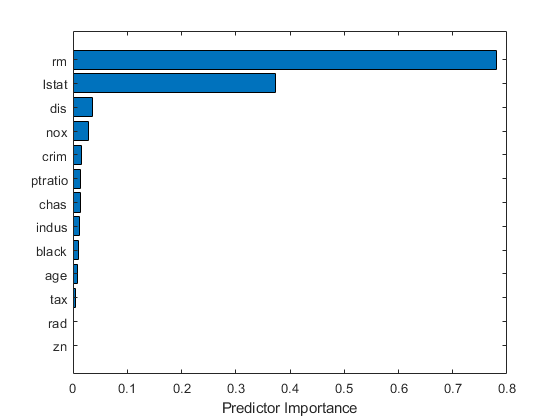

[predImportance,sortedIndex] = sort(predictorImportance(boostBoston));
figure;
barh(predImportance)
set(gca,'ytickLabel',boostBoston.PredictorNames(sortedIndex))
xlabel('Predictor Importance')

Create partial dependence plot (PDP) and individual conditional expectation (ICE) plots

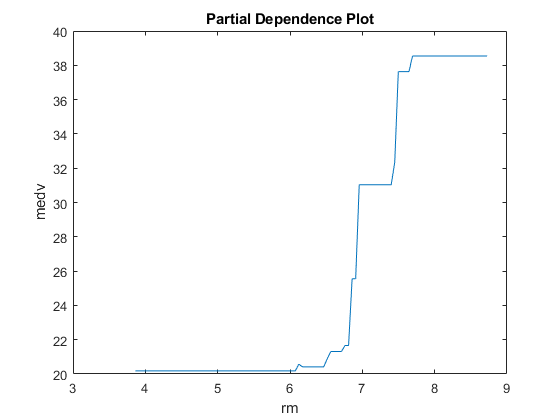

plotPartialDependence(boostBoston,'rm');

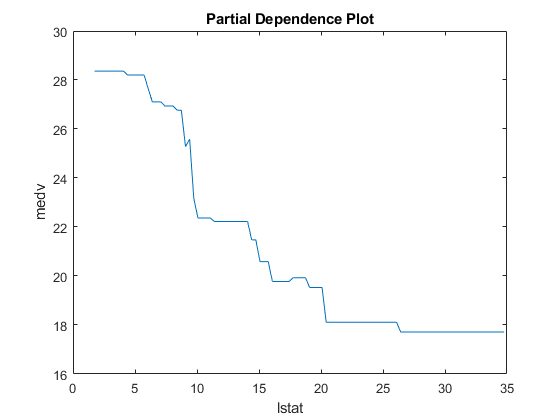

plotPartialDependence(boostBoston,'lstat');

Predict medv on the test set

yhatBoost = predict(boostBoston,Boston(cv.test,:));
mean((yhatBoost - Boston{cv.test,"medv"}).^2)

ans = 20.1105

% or
loss(boostBoston,Boston(cv.test,:),Boston(cv.test,"medv"),'mode','ensemble')

ans = 20.1105

Regularize and Shrink the Ensemble

We may not need all 500 trees to get the full accuracy for the model. We can regularize the weights and shrink based on a regularization parameter

% Try two different regularization parameter values for lasso
boostBostonRegularize = regularize(boostBoston,'lambda',[0.001 0.2]);
array2table([1:length(boostBostonRegularize.Regularization.Lambda);boostBostonRegularize.Regularization.Lambda],...
    'RowNames',{'#','lamda'})

ans = 2×2 table
             Var1     Var2
             _____    ____

    #            1      2 
    lamda    0.001    0.2 


disp('Number of Trees:')

Number of Trees:


disp(sum(boostBostonRegularize.Regularization.TrainedWeights > 0))

    10    10



% Shrink the ensemble using Lambda = 0.2
boostBoston1 = shrink(boostBostonRegularize,'weightcolumn',2);
% Calculate mean squared error (MSE)
fprintf('MSE with Lambda = 0.2 is %f\n',...
    loss(boostBoston1,Boston(cv.test,:),Boston(cv.test,"medv")));

MSE with Lambda = 0.2 is 19.446572


boostBoston2 = shrink(boostBostonRegularize,'weightcolumn',1);
fprintf('MSE with Lambda = 0.001 is %f\n',...
    loss(boostBoston2,Boston(cv.test,:),Boston(cv.test,"medv")));

MSE with Lambda = 0.001 is 19.508191
